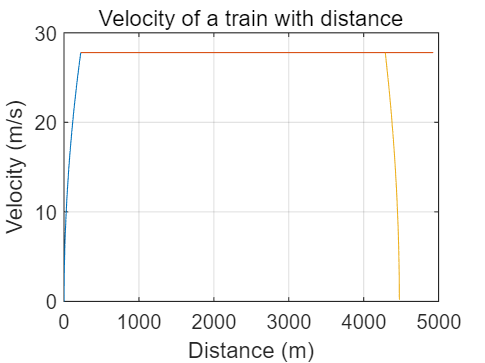


% 列车的质量
m = 176300;

% 列车的牵引力
F1 = 310000;

% 阻力
F3 = @(v) 2089.5+9.8 * v+6* v^2;

% 列车的初始速度
v0 = 0;

% 行驶时间范围
tspan = [0, 16];

% 定义微分方程
odefun = @(t, v) (F1 - F3(v)) / m;

% 使用 ode45 求解微分方程
[t, v] = ode45(odefun, tspan, v0);

% 计算列车行驶的距离
s = cumtrapz(t, v);

% 绘制速度-距离图像
plot(s, v);
xlabel('Distance (m)');
ylabel('Velocity (m/s)');
title('Velocity of a train with distance');
grid on;
hold on
x=[222.923 4928.46];
y=[27.7911 27.7911];
plot(x,y);
plot(s1,v1)
hold off

plot(s,t)
xlabel('s');
ylabel('t');
title('Velocity of a train with distance');
grid on;
hold on
x=[222.923 4928.46]

x = 1.0e+03 *

    0.2229    4.9285


y=[16 130725.361]

y = 1.0e+05 *

    0.0002    1.3073


plot(x,y)
x=[4928.46 5144.7]

x = 1.0e+03 *

    4.9285    5.1447


y=[130725.361 130740]

y = 1.0e+05 *

    1.3073    1.3074


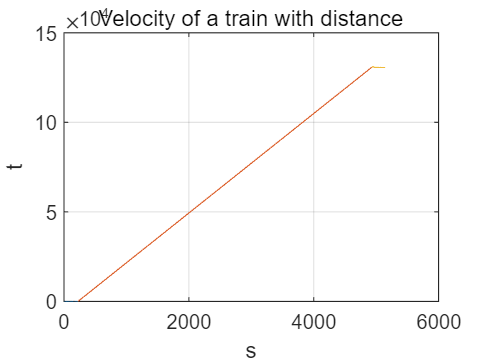

plot(s1,t1)
hold off

plot(s,E)
hold on
x=[222.923 4928.46]

x = 1.0e+03 *

    0.2229    4.9285


y=[69640500 102484000]

y =     69640500   102484000


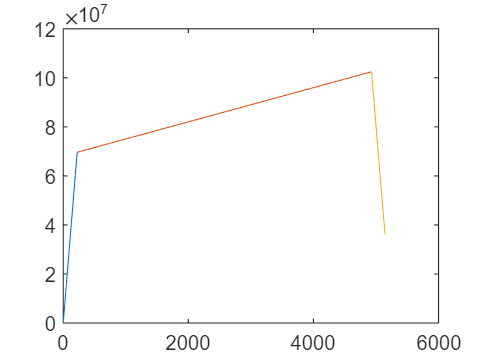

plot(x,y)
plot(s1,E1)
hold off

% 创建坡度条形图
bar(pd,'r');

函数或变量 'pd' 无法识别。

ylabel('Slope (%)');
slopeLimits=[-100 100]
ylim(slopeLimits);

% 创建最大速度限制折线图
speedLimits = [0 120];
yyaxis right
x=[1 12.5];
y=[100 100]
plot(x,y)
hold on
x=[12.5 18.5]
y=[86 86]
plot(x,y)
x=[18.5 20]
y=[100 100]
plot(x,y)
y=[100 86]
x=[12.5 12.5]
plot(x,y)
x=[18.5 18.5]
plot(x,y)
ylabel('Speed (km/h)');
ylim(speedLimits);

% 设置坐标轴标签
xlabel('Distance (km)');

% 合并图形
title('Slope and Speed Limits');
hold off
% % 绘制坡度条形图
% subplot(2,1,1);
% bar(pd);
% xlabel('坡度');
% ylabel('坡度值');
% title('坡度条形图');
% 
% % 绘制最大速度限制折线图
% subplot(2,1,2);
% plot(zdsd);
% xlabel('坡度');
% ylabel('最大速度');
% title('最大速度限制折线图');
% 
% % 同时设置两个子图的Y轴范围
% ylim([0, 0.1]); % 坡度图Y轴范围
% ylim([0, 100]); % 最大速度限制图Y轴范围